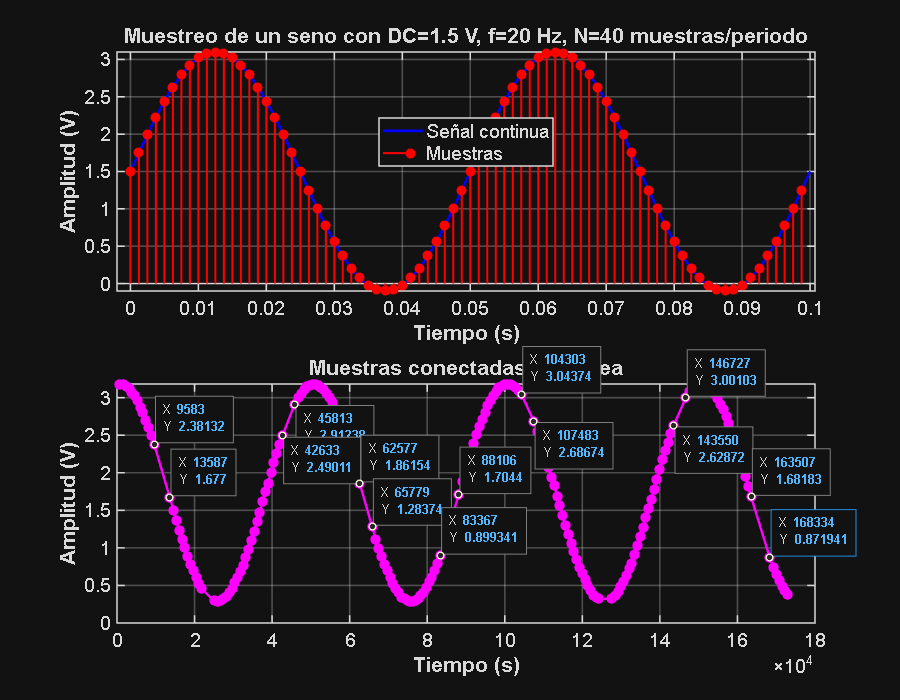

f = 20;        % frecuencia de la señal (Hz)
T = 1/f;        % periodo (s)
A = 1.6;        % amplitud (V)
NT = 2;         % nº de periodos a capturar
N = 40;         % nº de muestras por periodo
ts = T/N;       % periodo de muestreo (s)
dc = 1.5;       % componente DC (offset)

% Vector de tiempo para las muestras (N*NT puntos exactos)
t = 0:ts:(NT*T - ts);
V = dc + A * sin(2*pi*f*t);  % señal muestreada con DC

% Señal continua para comparación
t_cont = 0:ts/20:NT*T;
V_cont = dc + A * sin(2*pi*f*t_cont);

% ===== Gráfica con subplot =====
figure('Position',[100 100 900 700]);  % tamaño ventana más alto para dos plots

% Primer plot: señal continua y muestras
subplot(2,1,1) % 2 filas, 1 columna, 1er gráfico
plot(t_cont, V_cont, 'b-', 'LineWidth',2); hold on;
stem(t, V, 'r', 'filled', 'LineWidth',1.5);
xlabel('Tiempo (s)', 'FontSize',16, 'FontWeight','bold');
ylabel('Amplitud (V)', 'FontSize',16, 'FontWeight','bold');
title(sprintf('Muestreo de un seno con DC=%.1f V, f=%d Hz, N=%d muestras/periodo', dc, f, N), ...
      'FontSize',18, 'FontWeight','bold');
legend({'Señal continua', 'Muestras'}, 'FontSize',14, 'Location','best');
grid on;
set(gca, 'FontSize',14, 'LineWidth',1.2);

% Segundo plot: muestras conectadas con línea
subplot(2,1,2) % 2 filas, 1 columna, 2do gráfico
plot(t1, v1, 'm-o', 'LineWidth',1.8, 'MarkerSize',6, 'MarkerFaceColor','m');
xlabel('Tiempo (s)', 'FontSize',16, 'FontWeight','bold');
ylabel('Amplitud (V)', 'FontSize',16, 'FontWeight','bold');
title('Muestras conectadas con línea', 'FontSize',18, 'FontWeight','bold');
grid on;
set(gca, 'FontSize',14, 'LineWidth',1.2);